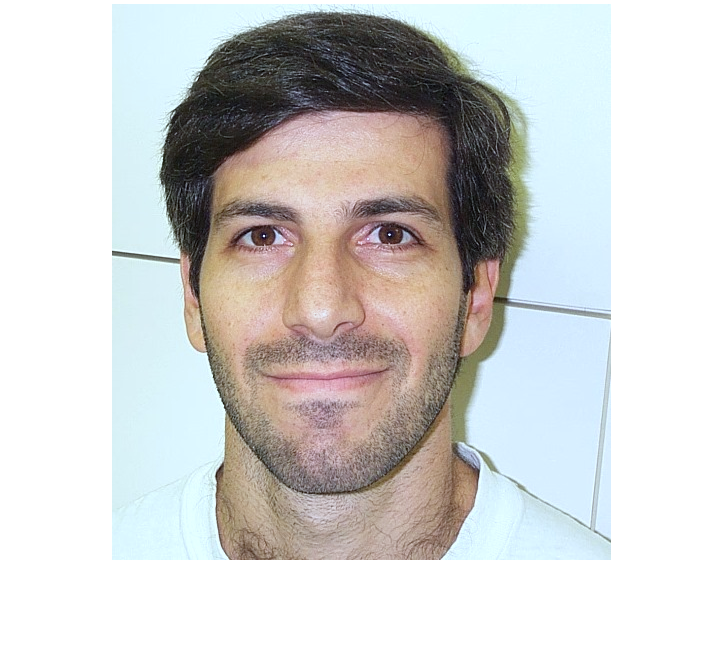

% Grey World Assumption 

img = imread("db1_09.jpg");

% Separate color channels
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Calculate average color
averageColor = (mean(R(:)) + mean(G(:)) + mean(B(:))) / 3;

% Calculate correction factor
correctionFactor = averageColor ./ [mean(R(:)), mean(G(:)), mean(B(:))];

% Apply correction to each channel
correctedImg = cat(3, R .* correctionFactor(1), G .* correctionFactor(2), B .* correctionFactor(3));

imshow(correctedImg)

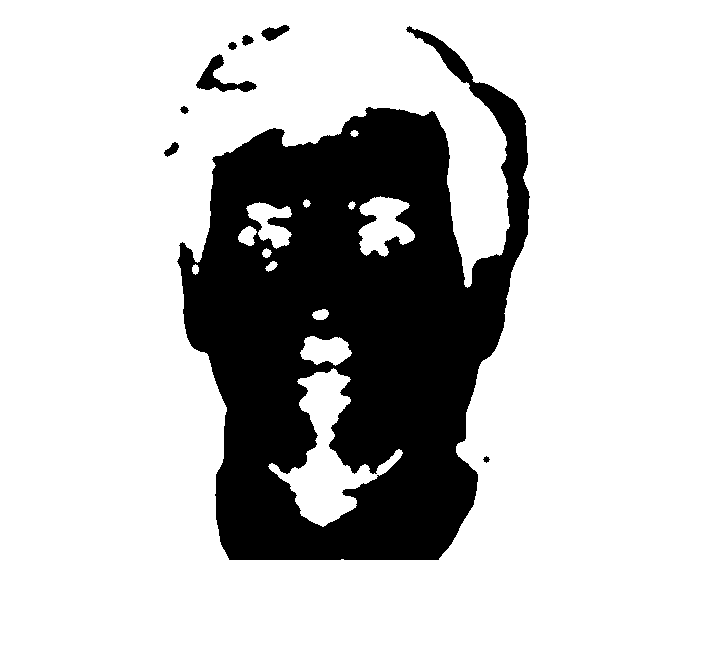


% Face mask

imgYCrBr1 = rgb2ycbcr(correctedImg); 

imgYCrBr = im2double(imgYCrBr1(:,:,2));

Tresh = graythresh(imgYCrBr);

TreshBin = imbinarize(imgYCrBr,Tresh);

kernel = ones(5,5)/(5*5);

bfilt = imfilter(imgYCrBr,kernel,'symmetric'); 

b_thresh = bfilt < Tresh;

r1=3;

SE = strel('sphere',r1);

TreshBin2 = imopen(b_thresh,SE);

TreshBin3 = imclose(TreshBin2,SE);

face_mask = 1 - TreshBin3;

imshow(face_mask)

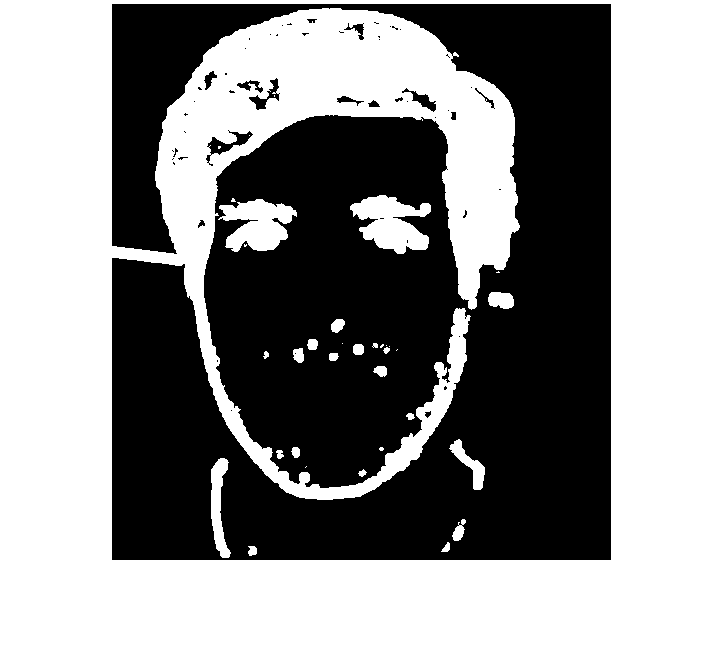


% Eye mask

LumChan = imgYCrBr1(:,:,1);
BlueChan = imgYCrBr1(:,:,2);
RedChan = imgYCrBr1(:,:,3);

CR_tilde_2 = (255 - RedChan); 

CB2 = (BlueChan);

CR_Div_CB = BlueChan ./ RedChan; 

EyeMapC = (1/3).*(CB2 + CR_tilde_2 + CR_Div_CB);

StructureBallSE = offsetstrel('ball',5,5);
Dialation = imdilate(LumChan,StructureBallSE); 

Erosion = imerode(LumChan,StructureBallSE);

EyeMapL = Dialation ./ (Erosion + 1);

EyeMapTotal = EyeMapC .* EyeMapL; 

EyeMapTotalDouble = im2double(EyeMapTotal);

EyeMapTotalScaled = EyeMapTotalDouble > 0.8;

imshow(EyeMapTotalScaled)

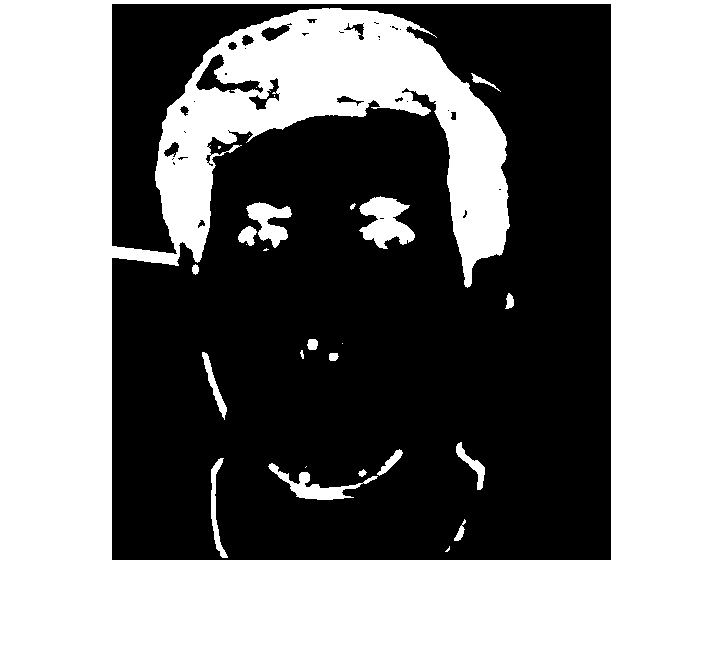


% Combination 

final = EyeMapTotalScaled & face_mask ; 

imshow(final)